# **電力負載分析**

**匯入資料**

data=readtable("electricity.xlsx");
head(data,20)

       Date        Residential    Commercial    Industrial      Total   
    ___________    ___________    __________    __________    __________

    01-Jan-1990     9.542e+07     6.2499e+07    7.5188e+07    2.4087e+08
    01-Feb-1990    7.4498e+07     5.6912e+07    7.4607e+07    2.1336e+08
    01-Mar-1990    7.1902e+07      5.798e+07    7.6842e+07    2.1407e+08
    01-Apr-1990    6.5191e+07     5.6481e+07    7.6238e+07    2.0507e+08
    01-May-1990    6.2881e+07     5.8941e+07    7.8759e+07    2.0815e+08
    01-Jun-1990      7.39e+07     6.4609e+07    8.0676e+07    2.2704e+08
    01-Jul-1990    9.0935e+07     7.0948e+07    8.1116e+07    2.5159e+08
    01-Aug-1990    8.8564e+07     7.1119e+07    8.4045e+07    2.5211e+08
    01-Sep-1990     8.624e+07     6.9296e+07    8.1611e+07    2.4518e+08
    01-Oct-1990    6.9595e

**資料前處理**

total=data.Total;
time=data.Date;
total_fill=fillmissing(total,"spline")

total_fill = 1.0e+08 *

    2.4087
    2.1336
    2.1407
    2.0507
    2.0815
    2.2704
    2.5159
    2.5211
    2.4518
    2.2231


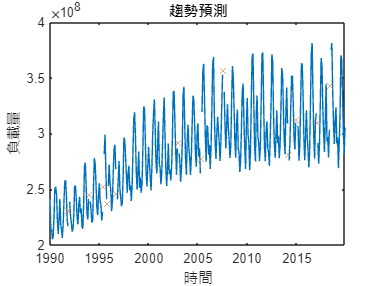

fill_pos=ismissing(total);

figure
plot(time,total);
hold on
plot(time(fill_pos),total_fill(fill_pos),'x')
hold off

title("趨勢預測")
xlabel("時間")
ylabel("負載量")

**趨勢預測**

x=years(time-time(1));
mdl=fitlm(x,total_fill,"quadratic")

mdl = Linear regression model:
    y ~ 1 + x1 + x1^2

Estimated Coefficients:
                    Estimate          SE         tStat       pValue   
                   ___________    __________    _______    ___________

    (Intercept)     2.1646e+08    4.0807e+06     53.045    2.2071e-171
    x1              7.6379e+06    6.3022e+05     12.119     1.5003e-28
    x1^2           -1.4809e+05         20396    -7.2609     2.4261e-12


Number of observations: 360, Error degrees of freedom: 357
Root Mean Squared Error: 2.6e+07
R-squared: 0.566,  Adjusted R-Squared: 0.563
F-statistic vs. constant model: 233, p-value = 2.2e-65

x_pred=linspace(0,35,500);

y_pred=predict(mdl,x_pred');

x_pred_dt=years(x_pred)+time(1)

x_pred_dt = 1×500 datetime array
   01-Jan-1990 00:00:00   26-Jan-1990 14:50:13   21-Feb-1990 05:40:26   18-Mar-1990 20:30:40   13-Apr-1990 11:20:53   09-May-1990 02:11:07   03-Jun-1990 17:01:20   29-Jun-1990 07:51:34   24-Jul-1990 22:41:47   19-Aug-1990 13:32:01   14-Sep-1990 04:22:14   09-Oct-1990 19:12:28   04-Nov-1990 10:02:41   30-Nov-1990 00:52:55   25-Dec-1990 15:43:08   20-Jan-1991 06:33:22   14-Feb-1991 21:23:35   12-Mar-1991 12:13:48   07-Apr-1991 03:04:02   02-May-1991 17:54:15   28-May-1991 08:44:29   22-Jun-1991 23:34:42   18-Jul-1991 14:24:56   13-Aug-1991 05:15:09   07-Sep-1991 20:05:23   03-Oct-1991 10:55:36   29-Oct-1991 01:45:50   23-Nov-1991 16:36:03   19-Dec-1991 07:26:17   13-Jan-1992 22:16:30   08-Feb-1992 13:06:44   05-Mar-1992 03:56:57   30-Mar-1992 18:47:10   25-Apr-1992 09:37:24   21-May-1992 00:27:37   15-Jun-1992 15:17:51   11-Jul-1992 06:08:04   05-Aug-1992 20:58:18   31-Aug-1992 11:48:31   26-Sep-1992 02:38:45   21-Oct-1992 17:28:58   16-Nov-1992 08:19:12 

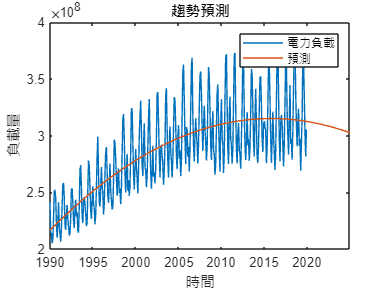


figure
plot(time,total_fill)
hold on
plot(x_pred_dt,y_pred)
hold off

title("趨勢預測")
xlabel("時間")
ylabel("負載量")
legend({"電力負載","預測"});